% TODO: По интерполяции использовать МАТЛАБ методы для более подробной сетки.

clc
close
clear

### **Практическая часть.**

Общие параметры.

TextSize = 15;

N = 100; % количество узлов 

x_left = 0;
x_right = 5; % диапазон изменения x

h = (x_right - x_left) / (N - 1); % шаг по x (равномерный)

x = x_left:h:x_right; % узловые точки
y = f_ot_x(x); % значение функции в узловых точках

График функции (по сеточным узлам).

figure(1);
plot(x, y, '-bo');
grid on;
title('График функции y = f(x)', 'FontSize', TextSize);
xlabel('Координата x', 'FontSize', TextSize);
ylabel('Координата y', 'FontSize', TextSize);

Ввод расчетной точки и проверка ее попадания в указанный диапазон.

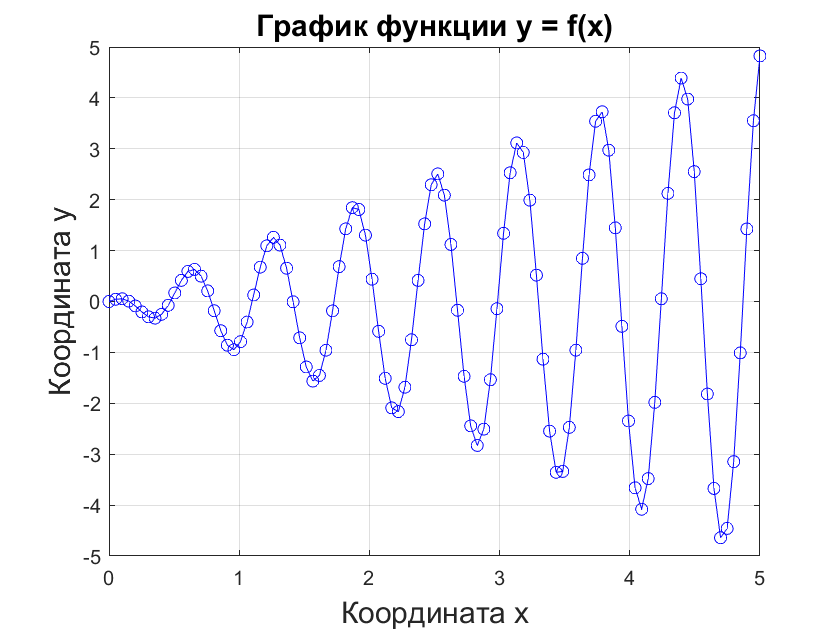

x0 = x_left - 1;
while  x0 > x_right || x0 < x_left
    
    x0_str =  inputdlg(['Введите значение х в диапазоне от: ' num2str(x_left) ' до ' num2str(x_right)], 'Расчетная точка', 1, {num2str(2.4)});
    x0 = str2double(x0_str{1});
    
end

Находим узлы слева и справа от заданной точки.

k_r = find((x > x0), 1, 'first'); % узел справа от точки
k_l = find((x < x0), 1, 'last'); % узел слева от точки

Интерполяция по Лагранжу первого порядка.

yL1 = y(k_r-1) * (x0 - x(k_r)) / (x(k_r-1) - x(k_r)) + y(k_r) * (x0 - x(k_r-1)) / (x(k_r) - x(k_r-1));

epsL1 = abs((yL1 - f_ot_x(x0)) / f_ot_x(x0)) * 100; % погрешность

Интерполяция по Лагранжу второго порядка (слева).

yL2l = y(k_l-1) * ((x0 - x(k_l)) * (x0 - x(k_l+1))) / ((x(k_l-1) - x(k_l)) * (x(k_l-1) - x(k_l+1))) + ...
       y(k_l) * ((x0 - x(k_l-1)) * (x0 - x(k_l+1))) / ((x(k_l) - x(k_l-1)) * (x(k_l) - x(k_l+1))) + ...
       y(k_l+1) * ((x0 - x(k_l-1)) * (x0 - x(k_l))) / ((x(k_l+1) - x(k_l-1)) * (x(k_l+1) - x(k_l)));

epsL2l = abs((yL2l - f_ot_x(x0)) / f_ot_x(x0)) * 100;

Интерполяция по Лагранжу второго порядка (справа).

yL2r = y(k_r-2) * ((x0 - x(k_r-1)) * (x0 - x(k_r))) / ((x(k_r-2) - x(k_r-1)) * (x(k_r-2) - x(k_r))) + ...
       y(k_r-1) * ((x0 - x(k_r-2)) * (x0 - x(k_r))) / ((x(k_r-1) - x(k_r-2)) * (x(k_r-1) - x(k_r))) + ...
       y(k_r) * ((x0 - x(k_r-2)) * (x0 - x(k_r-1))) / ((x(k_r) - x(k_r-2)) * (x(k_r) - x(k_r-1)));

epsL2r = abs((yL2r - f_ot_x(x0)) / f_ot_x(x0)) * 100;

Интерполяция по Лагранжу третьего порядка.

yL3 = y(k_r-3) * ((x0 - x(k_r-2)) * (x0 - x(k_r-1)) * (x0 - x(k_r))) / ((x(k_r-3) - x(k_r-2)) * (x(k_r-3) - x(k_r-1)) * (x(k_r-3) - x(k_r))) + ...
      y(k_r-2) * ((x0 - x(k_r-3)) * (x0 - x(k_r-1)) * (x0 - x(k_r))) / ((x(k_r-2) - x(k_r-3)) * (x(k_r-2) - x(k_r-1)) * (x(k_r-2) - x(k_r))) + ...
      y(k_r-1) * ((x0 - x(k_r-3)) * (x0 - x(k_r-2)) * (x0 - x(k_r))) / ((x(k_r-1) - x(k_r-3)) * (x(k_r-1) - x(k_r-2)) * (x(k_r-1) - x(k_r))) + ...
      y(k_r) * ((x0 - x(k_r-3)) * (x0 - x(k_r-2)) * (x0 - x(k_r-1))) / ((x(k_r) - x(k_r-3)) * (x(k_r) - x(k_r-2)) * (x(k_r) - x(k_r-1)));

epsL3 = abs((yL3 - f_ot_x(x0)) / f_ot_x(x0)) * 100;

Сплайн-интерполяция.

K = zeros(N-1, 1);
L = zeros(N-1, 1);

K(1) = 0;
L(1) = 0;

for i = 2:N-1
    
    hl = x(i) - x(i-1);
    hr = x(i+1) - x(i);
    a = hl / 6;
    b = (hl + hr) / 6;
    c = hr / 6;
    d = (y(i+1) - y(i)) / hr - (y(i) - y(i-1)) / hl;
    K(i) = -c / (a * K(i-1) + 2 * b);
    L(i) = (d - a * L(i-1)) / (a * K(i-1) + 2 * b);
    
end

m(N) = 0;

for i = (N-1):-1:1
    
    m(i) = K(i) * m(i+1) + L(i);
    
end

h = x(k_r) - x(k_r-1);
yS = m(k_r-1) * (x(k_r) - x0)^3 * h / 6 + m(k_r) * (x(k_r-1) - x0)^3 * h / 6 + ...
    (y(k_r-1) - m(k_r-1) * h^2 / 6) * (x(k_r) - x0) / h + (y(k_r) - m(k_r) * h^2 / 6) * (x0 - x(k_r-1)) / h;

epsS = abs((yS - f_ot_x(x0)) / f_ot_x(x0)) * 100;

Вывод результатов.

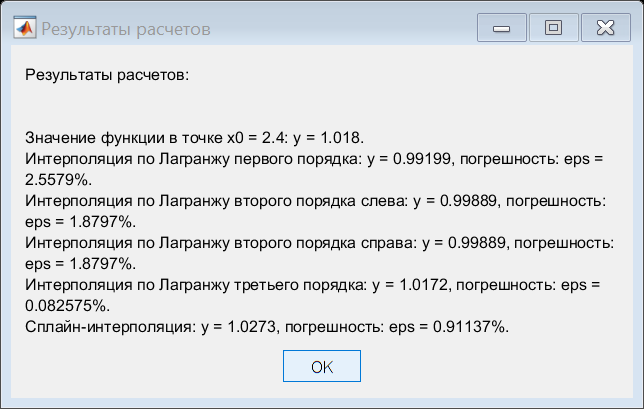

hMsg = msgbox({'Результаты расчетов: ', newline, ...
              ['Значение функции в точке x0 = ', num2str(x0), ': y = ' num2str(f_ot_x(x0)), '.'], ...
              ['Интерполяция по Лагранжу первого порядка: y = ', num2str(yL1), ', погрешность: eps = ', num2str(epsL1), '%.'], ...
              ['Интерполяция по Лагранжу второго порядка слева: y = ', num2str(yL2l), ', погрешность: eps = ', num2str(epsL2l), '%.'], ...
              ['Интерполяция по Лагранжу второго порядка справа: y = ', num2str(yL2r), ', погрешность: eps = ', num2str(epsL2r), '%.'], ...
              ['Интерполяция по Лагранжу третьего порядка: y = ', num2str(yL3), ', погрешность: eps = ', num2str(epsL3), '%.'], ...
              ['Cплайн-интерполяция: y = ', num2str(yS), ', погрешность: eps = ', num2str(epsS), '%.']
              }, 'Результаты расчетов');

### **Исследовательская часть.**

Реализация интерполяции с помощью библиотечных функций MATLAB с идентичными настройками методов.

yMat1 = interp1(x, y, x0, 'linear');
epsMat1 = abs((yMat1 - f_ot_x(x0)) / f_ot_x(x0)) * 100;

yMat2 = interp1(x, y, x0, 'previous');
epsMat2 = abs((yMat2 - f_ot_x(x0)) / f_ot_x(x0)) * 100;

yMat3 = interp1(x, y, x0, 'next');
epsMat3 = abs((yMat3 - f_ot_x(x0)) / f_ot_x(x0)) * 100;

yMat4 = interp1(x, y, x0, 'v5cubic');
epsMat4 = abs((yMat4 - f_ot_x(x0)) / f_ot_x(x0)) * 100;

yMat5 = interp1(x, y, x0, 'spline');
epsMat5 = abs((yMat5 - f_ot_x(x0)) / f_ot_x(x0)) * 100;

Сравнение значений y и eps между описанными в данной программе и библиотечными функциями.

yerr1 = abs((yMat1 - yL1) / yL1) * 100;
epserr1 = abs((epsMat1 - epsL1) / epsL1) * 100;

yerr2 = abs((yMat2 - yL2l) / yL2l) * 100;
epserr2 = abs((epsMat2 - epsL2l) / epsL2l) * 100;

yerr3 = abs((yMat3 - yL2r) / yL2r) * 100;
epserr3 = abs((epsMat3 - epsL2r) / epsL2r) * 100;

yerr4 = abs((yMat4 - yL3) / yL3) * 100;
epserr4 = abs((epsMat4 - epsL3) / epsL3) * 100;

yerr5 = abs((yMat5 - yS) / yS) * 100;
epserr5 = abs((epsMat5 - epsS) / epsS) * 100;

fprintf('Интерполяция по Лагранжу первого порядка (сравнение с MATLAB). \nОшибка по y: %d, по eps: %d.', yerr1, epserr1);

Интерполяция по Лагранжу первого порядка (сравнение с MATLAB). 
Ошибка по y: 0, по eps: 0.

fprintf('Интерполяция по Лагранжу второго порядка слева (сравнение с MATLAB). \nОшибка по y: %d, по eps: %d.', yerr2, epserr2);

Интерполяция по Лагранжу второго порядка слева (сравнение с MATLAB). 
Ошибка по y: 5.852517e+01, по eps: 3.054964e+03.

fprintf('Интерполяция по Лагранжу второго порядка справа (сравнение с MATLAB). \nОшибка по y: %d, по eps: %d.', yerr3, epserr3);

Интерполяция по Лагранжу второго порядка справа (сравнение с MATLAB). 
Ошибка по y: 5.269398e+01, по eps: 2.550581e+03.

fprintf('Интерполяция по Лагранжу третьего порядка (сравнение с MATLAB). \nОшибка по y: %d, по eps: %d.', yerr4, epserr4);

Интерполяция по Лагранжу третьего порядка (сравнение с MATLAB). 
Ошибка по y: 3.586178e-02, по eps: 4.339347e+01.

fprintf('Сплайн-интерполяция (сравнение с MATLAB). \nОшибка по y: %d, по eps: %d.', yerr5, epserr5);

Сплайн-интерполяция (сравнение с MATLAB). 
Ошибка по y: 9.136537e-01, по eps: 9.883525e+01.

Построение более подробной сетки.

x0_acc = x_left:(h/2):x_right;
yL1_acc = zeros(1, length(x0_acc));
yL2l_acc = zeros(1, length(x0_acc));
yL2r_acc = zeros(1, length(x0_acc));
yL3_acc = zeros(1, length(x0_acc));

for i = 1:length(x0_acc)
    
    k_r = find((x > x0_acc(i)), 1, 'first');
    
    if k_r - 1 < 1 || k_r > length(x)
        
        continue;
        
    else
        
        yL1_acc(i) = y(k_r-1) * (x0_acc(i) - x(k_r)) / (x(k_r-1) - x(k_r)) + y(k_r) * (x0_acc(i) - x(k_r-1)) / (x(k_r) - x(k_r-1));
        
    end
    
end

for i = 2:length(x0_acc)
    
    k_l = find((x < x0_acc(i)), 1, 'last');
    
    if k_l - 1 < 1 || k_l + 1 > length(x)
        
        continue;
        
    else
        
        yL2l_acc(i) = y(k_l-1) * ((x0_acc(i) - x(k_l)) * (x0_acc(i) - x(k_l+1))) / ((x(k_l-1) - x(k_l)) * (x(k_l-1) - x(k_l+1))) + ...
        y(k_l) * ((x0_acc(i) - x(k_l-1)) * (x0_acc(i) - x(k_l+1))) / ((x(k_l) - x(k_l-1)) * (x(k_l) - x(k_l+1))) + ...
        y(k_l+1) * ((x0_acc(i) - x(k_l-1)) * (x0_acc(i) - x(k_l))) / ((x(k_l+1) - x(k_l-1)) * (x(k_l+1) - x(k_l)));
   
    end
    
end

for i = 1:length(x0_acc)
    
    k_r = find((x > x0_acc(i)), 1, 'first');
    
    if k_r - 2 < 1 || k_r - 1 < 1 || k_r > length(x)
        
        continue;
        
    else
        
        yL2r_acc(i) = y(k_r-2) * ((x0_acc(i) - x(k_r-1)) * (x0_acc(i) - x(k_r))) / ((x(k_r-2) - x(k_r-1)) * (x(k_r-2) - x(k_r))) + ...
        y(k_r-1) * ((x0_acc(i) - x(k_r-2)) * (x0_acc(i) - x(k_r))) / ((x(k_r-1) - x(k_r-2)) * (x(k_r-1) - x(k_r))) + ...
        y(k_r) * ((x0_acc(i) - x(k_r-2)) * (x0_acc(i) - x(k_r-1))) / ((x(k_r) - x(k_r-2)) * (x(k_r) - x(k_r-1)));
   
    end
    
end

for i = 1:length(x0_acc)
    
    k_r = find((x > x0_acc(i)), 1, 'first');
    
    if k_r - 3 < 1 || k_r - 2 < 1 || k_r - 1 < 1 || k_r > length(x)
        
        continue;
        
    else
        
        yL3_acc(i) = y(k_r-3) * ((x0_acc(i) - x(k_r-2)) * (x0_acc(i) - x(k_r-1)) * (x0_acc(i) - x(k_r))) / ((x(k_r-3) - x(k_r-2)) * (x(k_r-3) - x(k_r-1)) * (x(k_r-3) - x(k_r))) + ...
        y(k_r-2) * ((x0_acc(i) - x(k_r-3)) * (x0_acc(i) - x(k_r-1)) * (x0_acc(i) - x(k_r))) / ((x(k_r-2) - x(k_r-3)) * (x(k_r-2) - x(k_r-1)) * (x(k_r-2) - x(k_r))) + ...
        y(k_r-1) * ((x0_acc(i) - x(k_r-3)) * (x0_acc(i) - x(k_r-2)) * (x0_acc(i) - x(k_r))) / ((x(k_r-1) - x(k_r-3)) * (x(k_r-1) - x(k_r-2)) * (x(k_r-1) - x(k_r))) + ...
        y(k_r) * ((x0_acc(i) - x(k_r-3)) * (x0_acc(i) - x(k_r-2)) * (x0_acc(i) - x(k_r-1))) / ((x(k_r) - x(k_r-3)) * (x(k_r) - x(k_r-2)) * (x(k_r) - x(k_r-1)));
   
    end
    
end

Вывод графиков.

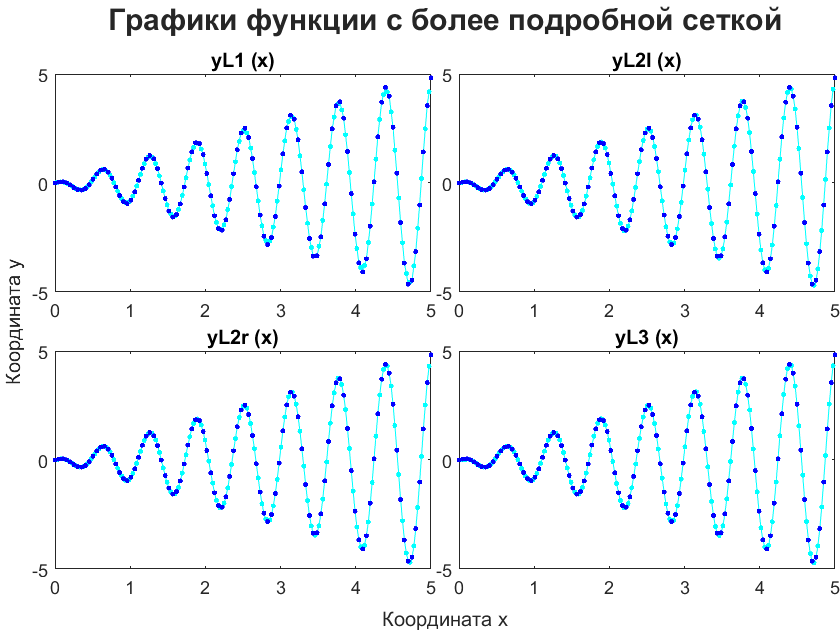

figure(2)
tl = tiledlayout(2,2);
tl.TileSpacing = 'none';
tl.Padding = 'none';

ax1 = nexttile;
plot(x0_acc, yL1_acc, '-c.', x, y, 'b.');
title('yL1 (x)', 'FontSize', TextSize);

ax2 = nexttile;
plot(x0_acc, yL2l_acc, '-c.', x, y, 'b.');
title('yL2l (x)', 'FontSize', TextSize);

ax3 = nexttile;
plot(x0_acc, yL2r_acc, '-c.', x, y, 'b.');
title('yL2r (x)', 'FontSize', TextSize);

ax4 = nexttile;
plot(x0_acc, yL3_acc, '-c.', x, y, 'b.');
title('yL3 (x)', 'FontSize', TextSize);

linkaxes([ax1, ax2, ax3, ax4], 'x');
title(tl, 'Графики функции с более подробной сеткой', 'FontWeight', 'bold', 'FontSize', TextSize)
xlabel(tl, 'Координата x', 'FontSize', TextSize-5);
ylabel(tl, 'Координата y', 'FontSize', TextSize-5);